# **BS1 USRP N310 Transmitter **

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 512;              % FFT length
OFDMParams.CPLength               = ceil(OFDMParams.FFTLength*0.25);   % Cyclic prefix length
RB                                = 36;                                % User input Resource block number
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing

% 调用calculateRBFinal函数确保最终的RB确定的子载波总数能够被pilot subcarrier spacing整除
[RB_verified, MaxRB] = calculateRBFinal(OFDMParams, RB);

% check if RB_verified exceed MaxRB
if RB_verified > MaxRB
    error('Error: Defined RB (%d) exceeds the system maximum allowed RB (%d). ', RB_verified, MaxRB);
end

% 将最终确定的RB赋给OFDMParam参数
OFDMParams.RB                     = RB_verified;
OFDMParams.NumSubcarriers         = OFDMParams.RB*12;                  % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
OFDMParams.Subcarrierspacing      = 30e3;              % Sub-carrier spacing of 30 KHz
OFDMParams.channelBW              = (OFDMParams.FFTLength+OFDMParams.NumSubcarriers)*OFDMParams.Subcarrierspacing*0.5;   % Bandwidth of the channel

% check if NumSubcarriers less than FFTLength
if OFDMParams.NumSubcarriers > OFDMParams.FFTLength
    error('NumSubcarriers: (%d) exceeds FFTLength: (%d), which is not allowed. Please reduce the value of RB.', ...
        OFDMParams.NumSubcarriers, OFDMParams.FFTLength);
end

% Data Parameters
dataParams.modOrder       = 64;   % Data modulation order
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame 20 for setup1
dataParams.numFrames      = 10000;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.printunderflow   = true;                    % Switch to enable or disable the print of underflow 
dataParams.verbosity      = true;                    % Switch to enable or disable the data diagnostic output

## Initialize Transmitter Parameters

radioDevice            = "N310";  % Choose the radio device for transmission
channelmapping         = 1;  % mutichannel or single channel selection
centerFrequency        = 2.5e9;  % Center Frequency
gain                   = 50;  % Set radio gain
% gain                   = 40

[sysParam,txParam,trBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate               = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
ofdmTx                   = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain,channelmapping);

Checking radio connections...



% Get the radio transmitter and spectrum analyzer system object system object for the user to visualize the transmitted waveform.
[radio,spectrumAnalyze] = helperGetRadioTxObj(ofdmTx);
radio.TransportDataType = "int16";

## Generate Transmitter Waveform 

### **Transmit Frame Structure**

**Synchronization Symbol (SS)**

**Reference Symbol (RS)**

**Header Symbol**

**Pilot Signals**

**DC and Guard Subcarriers**

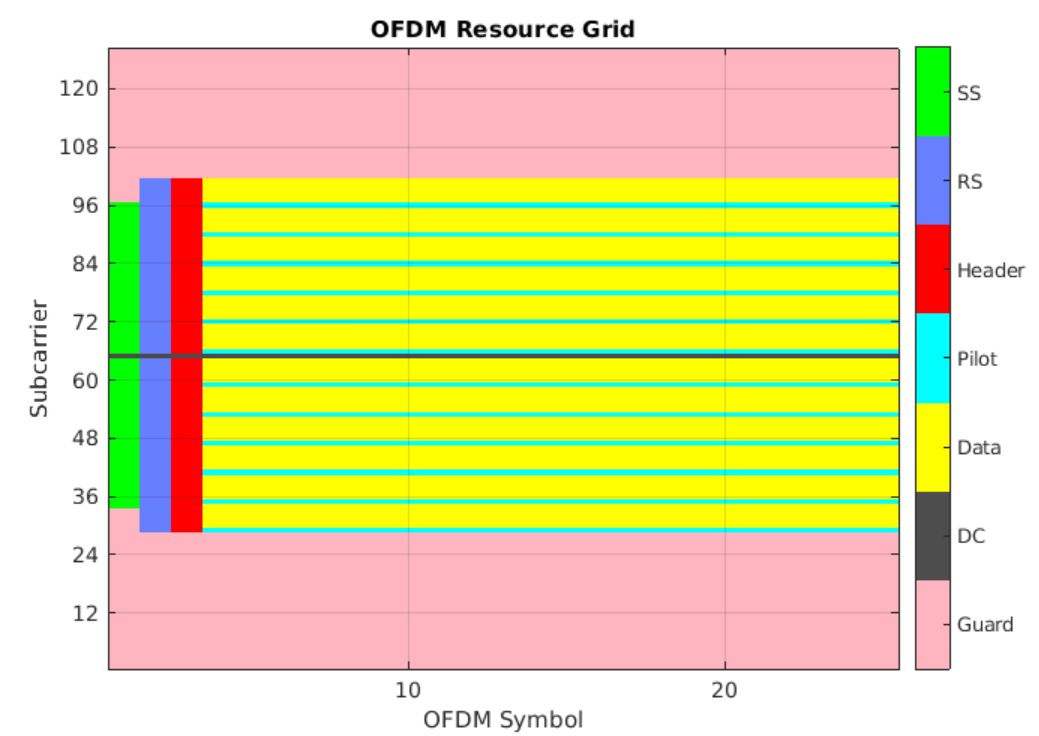

### Transmitter processing

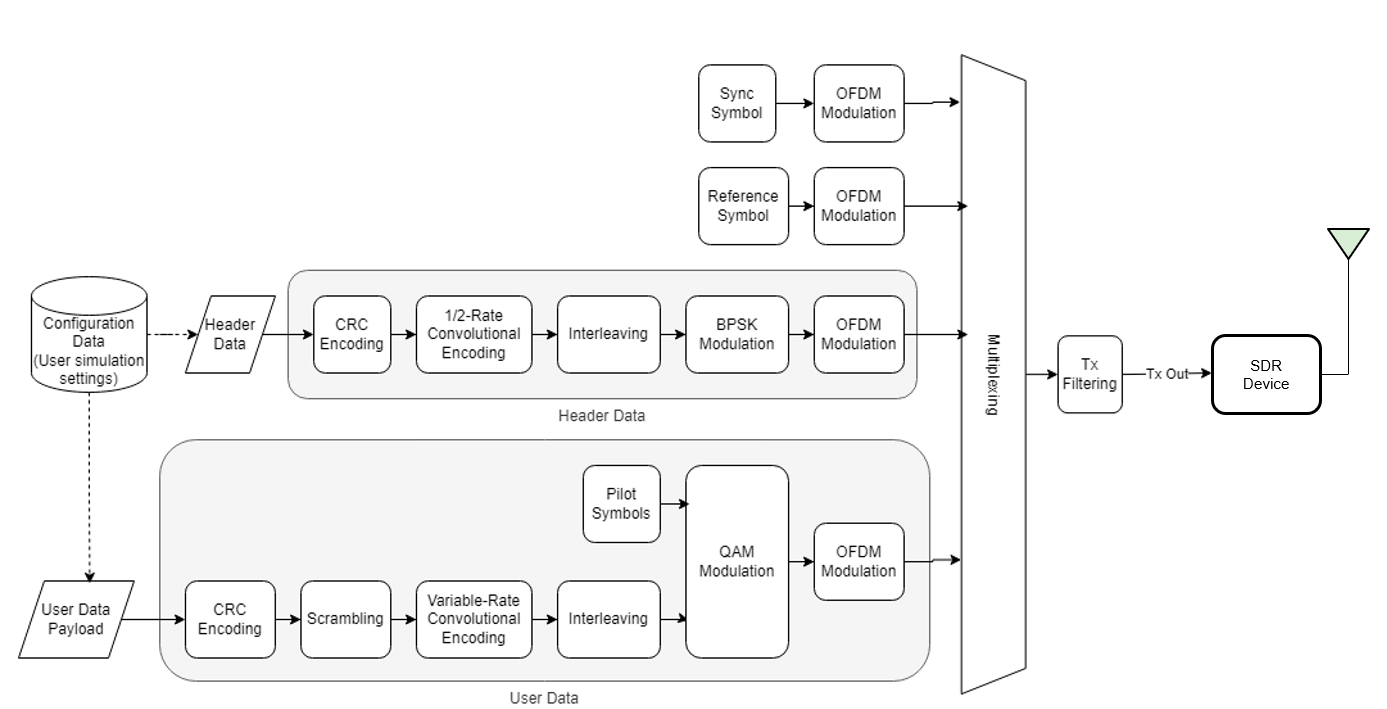

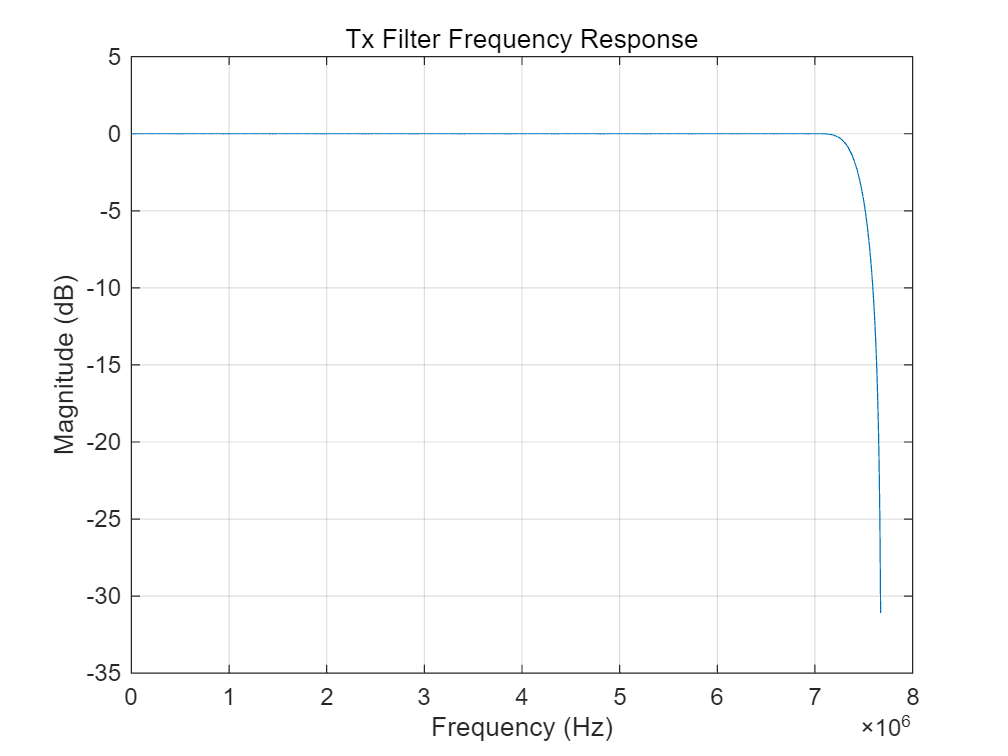


% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);

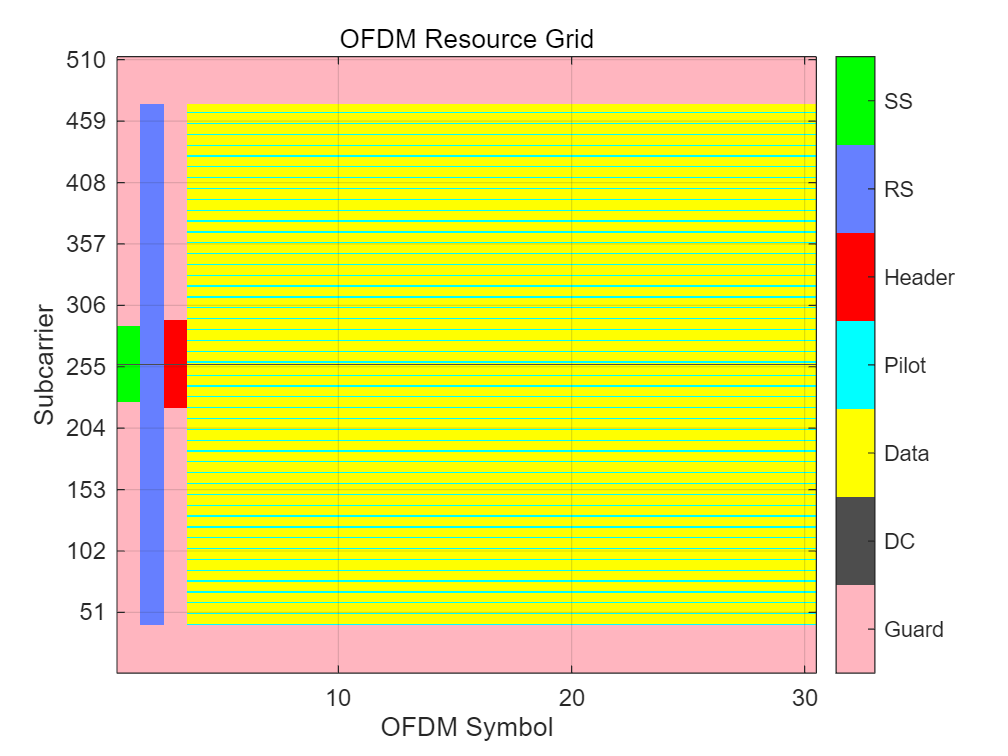

tunderrun = 0; % Initialize count for underruns

% A known payload is generated in the function helperOFDMSetParams with
% respect to the calculated trBlkSize
% Store data bits for BER calculations
txParam.txDataBits = trBlk;
[txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

% Display the grid if verbosity flag is enabled
if dataParams.verbosity
    helperOFDMPlotResourceGrid(txGrid,sysParam);
end

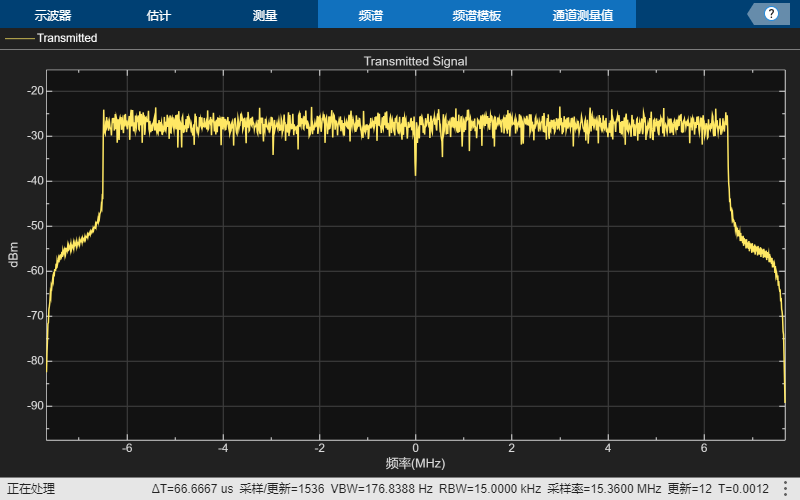


% Repeat the data in a buffer for PLUTO radio to make sure there are less
% underruns. The receiver decodes only one frame from where the first
% synchroization signal is received
txOutSize = length(txOut);
if contains(radioDevice,'PLUTO') && txOutSize < 48000
    frameCnt = ceil(48000/txOutSize);
    txWaveform = zeros(txOutSize*frameCnt,1);
    for i = 1:frameCnt
        txWaveform(txOutSize*(i-1)+1:i*txOutSize) = txOut;
    end
else
    txWaveform = txOut;
end

if dataParams.enableScopes
    spectrumAnalyze(txOut);
end

transmit_flag = 0;
txWaveform = [txWaveform];
% txWaveform = [txWaveform,txWaveform];
% txWaveform = [txWaveform,txWaveform,txWaveform,txWaveform];


## Transmit Over Radio

for frameNum = 1:sysParam.numFrames+1
    underrun = radio(txWaveform);
    tunderrun = tunderrun + underrun;  % Total underruns
    if transmit_flag == 0
        fprintf('-----------BS1 N310 starting transmitting at Rfq %s!----------------\n', mat2str(centerFrequency))
        fprintf('-----------TR antennal %s----------------\n', mat2str(channelmapping))
        fprintf('-----------Gain %s----------------', mat2str(gain))
        transmit_flag = 1;
    end
    if underrun > 0
        if dataParams.printunderflow
            fprintf('Underrun occurred at frame number: %d\n', frameNum);
    
        end
    end
end

-----------BS1 N310 starting transmitting at Rfq 2500000000!----------------


-----------TR antennal 1----------------


-----------Gain 50----------------

if transmit_flag == 1
    fprintf('----------BS1 N310 ending of transmitting at Rfq %s!-------------', mat2str(centerFrequency))
end

----------BS1 N310 ending of transmitting at Rfq 2500000000!-------------

% 输出总的underrun数目
fprintf('Total number of underruns: %d\n', tunderrun);

Total number of underruns: 0


% radio.CenterFrequency = 3.1e9;
% transmit_flag = 0;
% for frameNum = 1:sysParam.numFrames+1
%     underrun = radio(txWaveform);
%     tunderrun = tunderrun + underrun;  % Total underruns
%     if transmit_flag == 0
%         fprintf('-----------starting transmitting at frequency band 2!----------------')
%         transmit_flag = 1;
%     end
% end
% if transmit_flag == 1
%     fprintf('----------ending of transmitting at frequency band 2-------------')
% end

% Clean up the radio System object
release(radio);